# **Ejercicio 2.1: Modelado de sistema Volterra-Lotka**

%Definición de parámetros del sistema, intervalos de evaluación y estado
%inicial

[a, b, c, d] = deal(1.5, 1, 0.2, 0.7);
x0 = [10; 7];
tspan = [0,10];

%Integración de las ecuaciones del sistema
[t, x] = ode45(@(t,x)lotkavolterra(t, x, a, b, c, d), tspan, x0)

t =          0
    0.0084
    0.0167
    0.0251
    0.0335
    0.0754
    0.1172
    0.1591
    0.2010
    0.2488


x =    10.0000    7.0000
   10.0054    7.3608
   10.0046    7.7403
    9.9972    8.1391
    9.9831    8.5580
    9.8009   10.9677
    9.4048   13.9486
    8.7799   17.4811
    7.9441   21.4347
    6.7947   26.1709


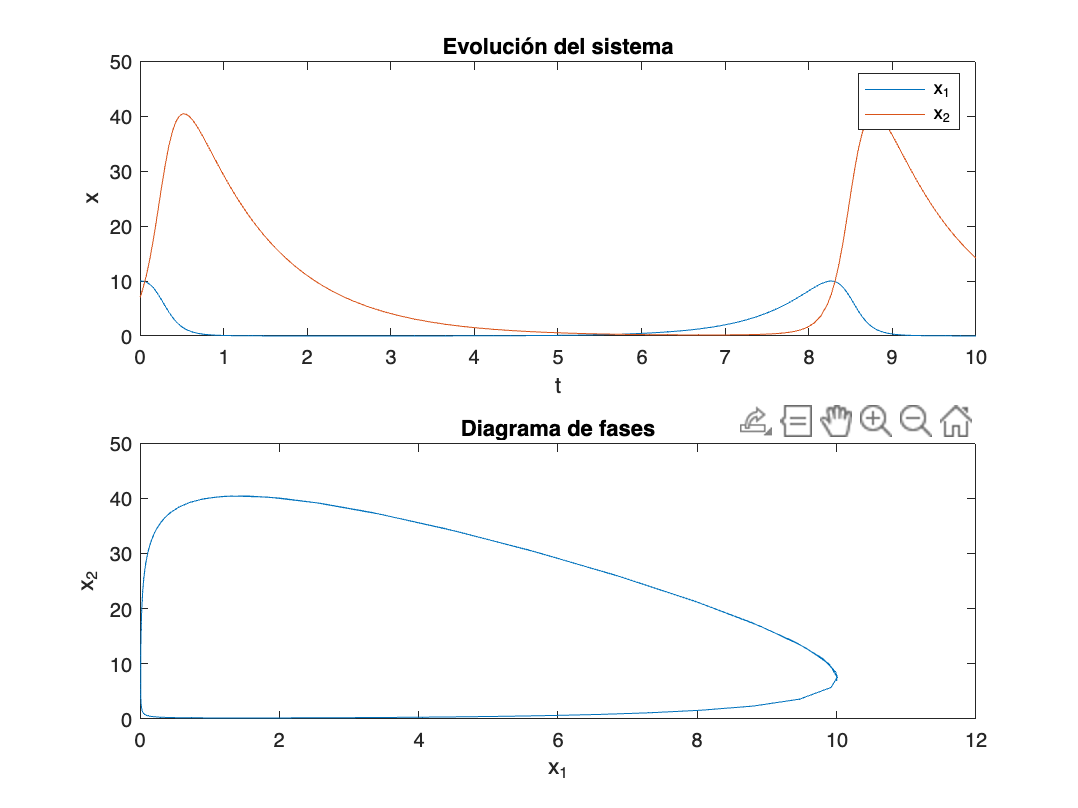


%Gráficas
figure(1)
subplot(2, 1, 1)
plot(t, x)
title("Evolución del sistema")
legend("x_1", "x_2")
ylabel("x")
xlabel("t")

subplot(2, 1, 2)
plot(x(:,1), x(:,2))
title("Diagrama de fases")
ylabel("x_2")
xlabel("x_1")

**Funciones**

function xdot = lotkavolterra(t, x, a, b, c, d)
    
    %El sistema es autónomo pero se necesita el parámetro t para que funcione ODE45.
    %La entrada y la salida son vectores de dos filas y una columna. 
    
    xdot(1,1) = a * x(1,1) - c * x(1,1) * x(2,1);
    xdot(2,1) = -b * x(2,1) + d * x(1,1) * x(2,1);

end